# Integration of Filippov behaviour in switched ODE systems

When integrating a switched system, rapid switching behavoiur can occur if the vector fields (created by the RHS) point towards each other around the switch. This is called **Filippov switching behaviour**. A naive integrator such as the explicit euler (but also more sophisticated ones such as ode45) fails to capture the fact that in such a case the solution slides along the so called switching manifold (a body in the solution space containing all points, where the RHS branches to different versions).

Even an *accurate* Euler as shown further down in the document cannot capture a sufficiently accurate trajectory and takes up a lot of computational time, effort and working memory. `IFDIFF` on the other hand can spot such behaviour stepping **along** the corresponding surface using information of both neighboring models in a convex combination. In this case the linked integrator can still choose adaptive step sizes and shows no real drop in performance.

## A switched Predator-Prey model

First the differential equation is initialized. Its formualtion can be found [here](matlab:open('..\predatorprey_filippov\pprhs.m')).

m     = 0.790;
r1    = 0.836;
e     = 0.948;
q1    = 0.772;
aq    = 0.660;
beta2 = 0.896;
beta1 = 7.81; 
q2    = 1.5; 
r2    = 0.3;

a = 0.286975;
x0_1 = [a ; a ; r1-r2];
p = [r1, r2, beta1, beta2, q1, q2, m, e, aq];
tspan = [0 100];

% plotting grid and figure
X_plot = linspace(tspan(1), tspan(end), 1000);
fignum = 1000; 
figure(fignum); clf; hold on;
plotit = @plotter;

% solver configuration (IFDIFF path)
intIfdiff  = @ode45;
intOptions = odeset('reltol', 1e-5, 'abstol', 1e-5, 'MaxStep', 0.5);

% labels
nameIfdiff = @(f) sprintf('ifdiff/%s', func2str(f));
nameEuler  = 'plain Euler (loaded)';

% expected Euler filename (in the same folder as this live script)
eulerStep  = 1e-7;
euler_fname = sprintf('sol_euler_%.0e.mat', eulerStep);

%% IFDIFF integration
datahandle = prepareDatahandleForIntegration('pprhs', 'solver', func2str(intIfdiff), 'options', intOptions);
sol_ifdiff = solveODE(datahandle, tspan, x0_1, p);

Y_ifdiff   = deval(sol_ifdiff, X_plot);
hIFDIFF    = plotit(fignum, Y_ifdiff, 'g', nameIfdiff(intIfdiff), 3.0);

As was already mentioned, the "accurate" Euler solution is only loaded from a precomputed file as the computation with the above stepsize takes quite long. Even so the Euler-solution is not at all accurate, since the corresponding algorithm doesn't account for any of the switches (which in this case are thousands). As much can be seen in the difference plot below.

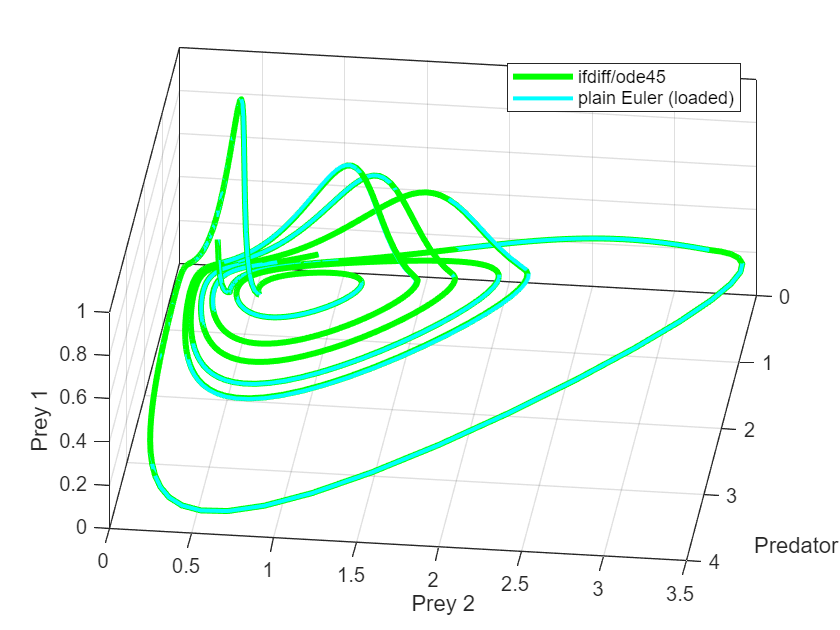

S = load(euler_fname, 'sol_euler');
sol_euler = S.sol_euler;
Y_euler   = transpose(interp1(sol_euler.x, transpose(sol_euler.y), X_plot));
hEuler    = plotit(fignum, Y_euler, 'c', nameEuler, 2.0);

## Difference Plot between "accurate" Euler solution and `IFDIFF`

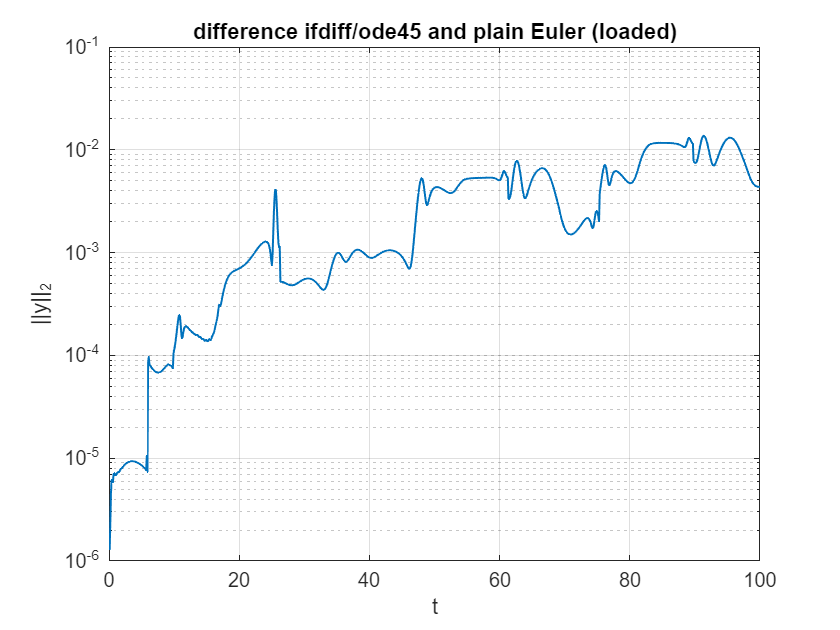

fignum = fignum + 1; 
errorPlot(fignum, X_plot, Y_ifdiff, Y_euler, nameIfdiff(intIfdiff), nameEuler);